# OGLO notebook 4a

hnxj@github

## 1: Time-frequency analysis

% aaab = 1;
% axab = 2;
% aaxb = 3;
% aaax = 4;
% bbba = 5;
% bxba = 6;
% bbxa = 7;
% bbbx = 8;
% rrrr = 9;
% rxrr = 10;
% rrxr = 11;
% rrrx = 12;

nPath = "lfpData\";

1. loaded : 01_LFPs_OGLO_V1.mat
2. loaded : 02_LFPs_OGLO_V2.mat
3. loaded : 03_LFPs_OGLO_V3a.mat
4. loaded : 04_LFPs_OGLO_V3d.mat


nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

z = cell(1, 10);

for i = 1:4

    nFile = nFiles{i};
    z{i} = load(nPath + nFile).z;
    disp(num2str(i) + ". loaded : " + nFile);

end

order : [area{1-10}, cond{1-12}, sess{1-s*}]

- PSpectrums (X, fs, fLim);

- AAAB vs AAAX, BBBA vs BBBX, RRRR vs RRRX spectral analysis (10 areas)

### V1

xG = z{1};

y = squeeze(mean(xG3(:, 39, :), 1));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx = zeros([12, size(p1)]);

for ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx(ik, :, :) = squeeze(pgx(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 1
cond : 2
cond : 3
cond : 4
cond : 5
cond : 6
cond : 7
cond : 8
cond : 9
cond : 10
cond : 11
cond : 12


% pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs01_OGLO_V1", "pgx_v1", "-v7.3");

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        pgx(ij, ik, :) = (pgx_v1(ij, ik, :))/mean(pgx_v1(ij, ik, 1:15));

    end

end

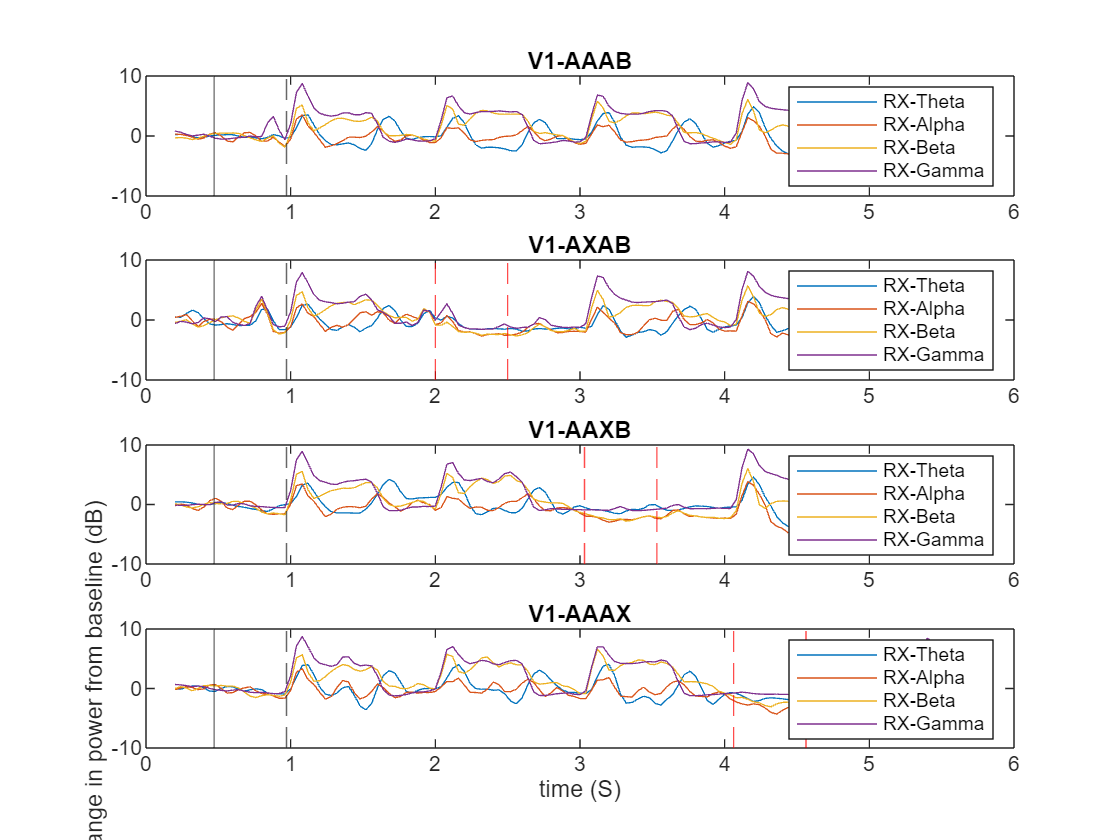

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V1-AAAB");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-AXAB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-AAXB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V1-AAAX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V1_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

### V2

xG = z{2};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx_v2 = zeros([12, size(p1)]);

for ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx_v2(ik, :, :) = squeeze(pgx_v2(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 1
cond : 2
cond : 3
cond : 4
cond : 5
cond : 6
cond : 7
cond : 8
cond : 9
cond : 10
cond : 11
cond : 12


y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs02_OGLO_V2", "pgx_v2", "-v7.3");

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        pgx(ij, ik, :) = (pgx_v2(ij, ik, :))/mean(pgx_v2(ij, ik, 1:15));

    end

end

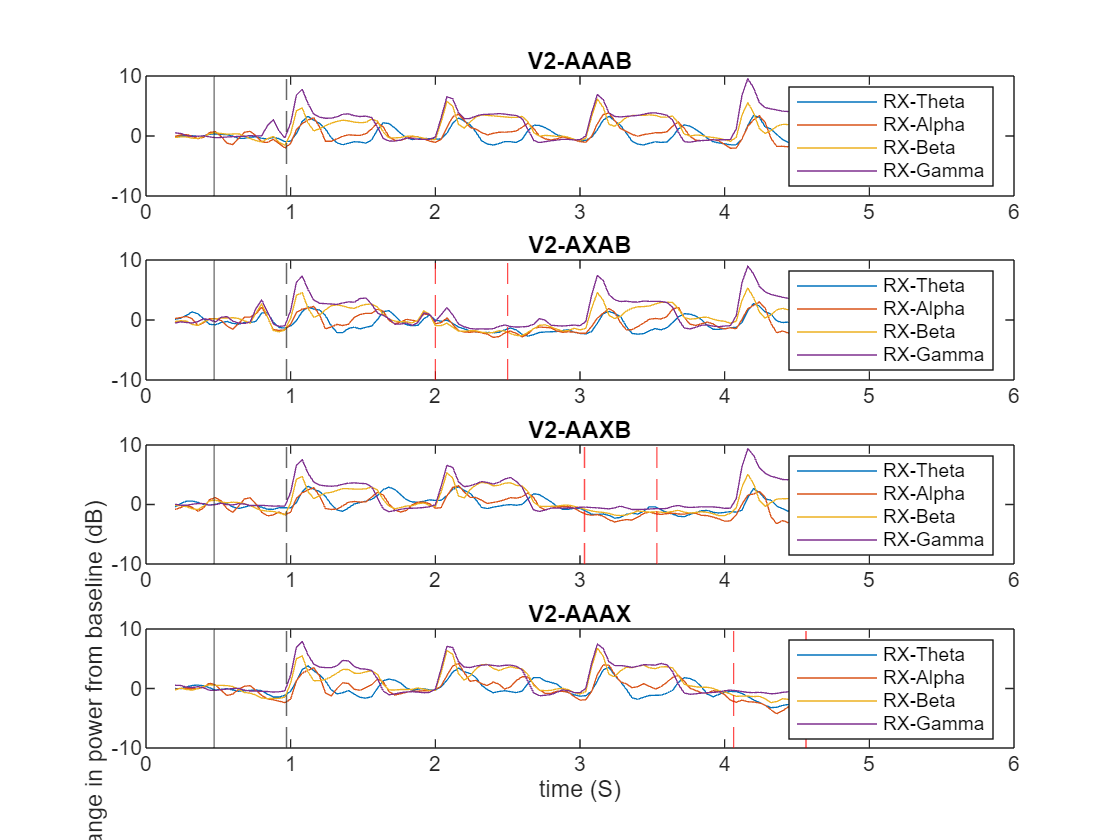

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V2-AAAB");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-AXAB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-AAXB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");

xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V2-AAAX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V2_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

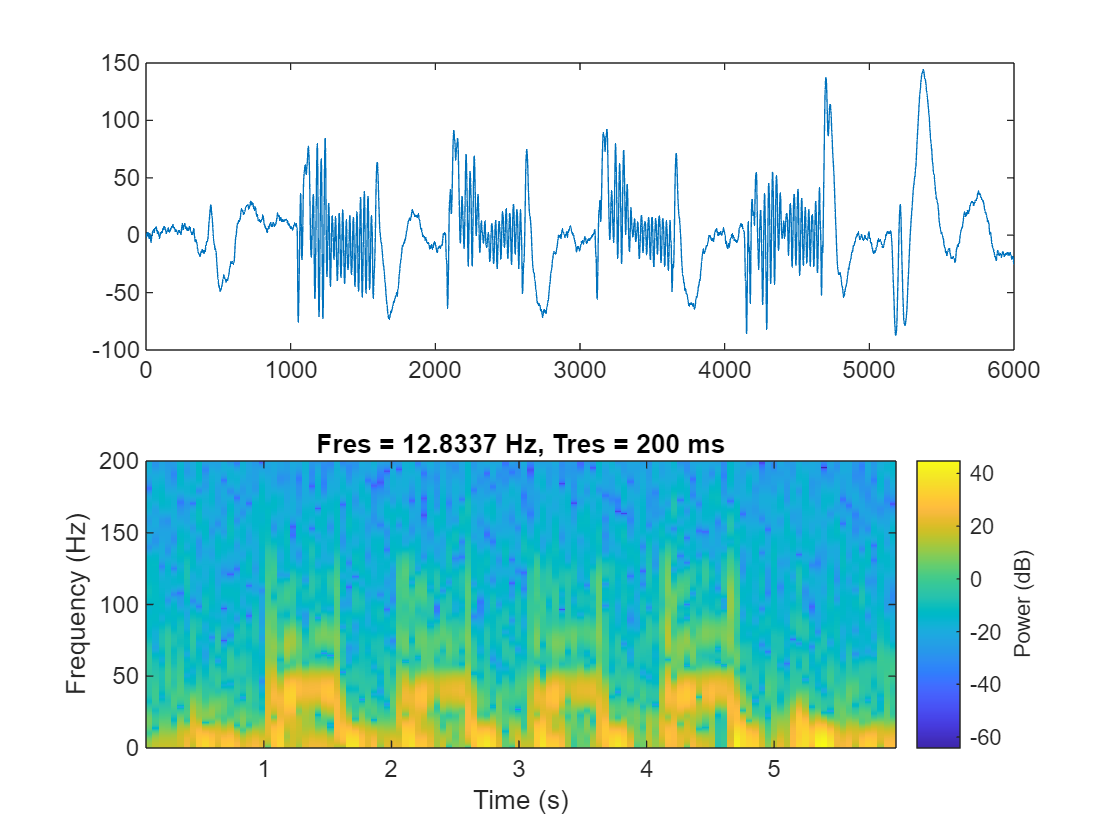

function Y = mvpa_weights(X, G)
% MVPA_WEIGHTS - Perform multivariate pattern analysis (MVPA) using SVM
% Inputs:
%   X - Data matrix (N groups x M channels x T time points)
%   G - Group labels (1 x N group labels)
% Outputs:
%   Y - Weight matrix (N groups x M channels)

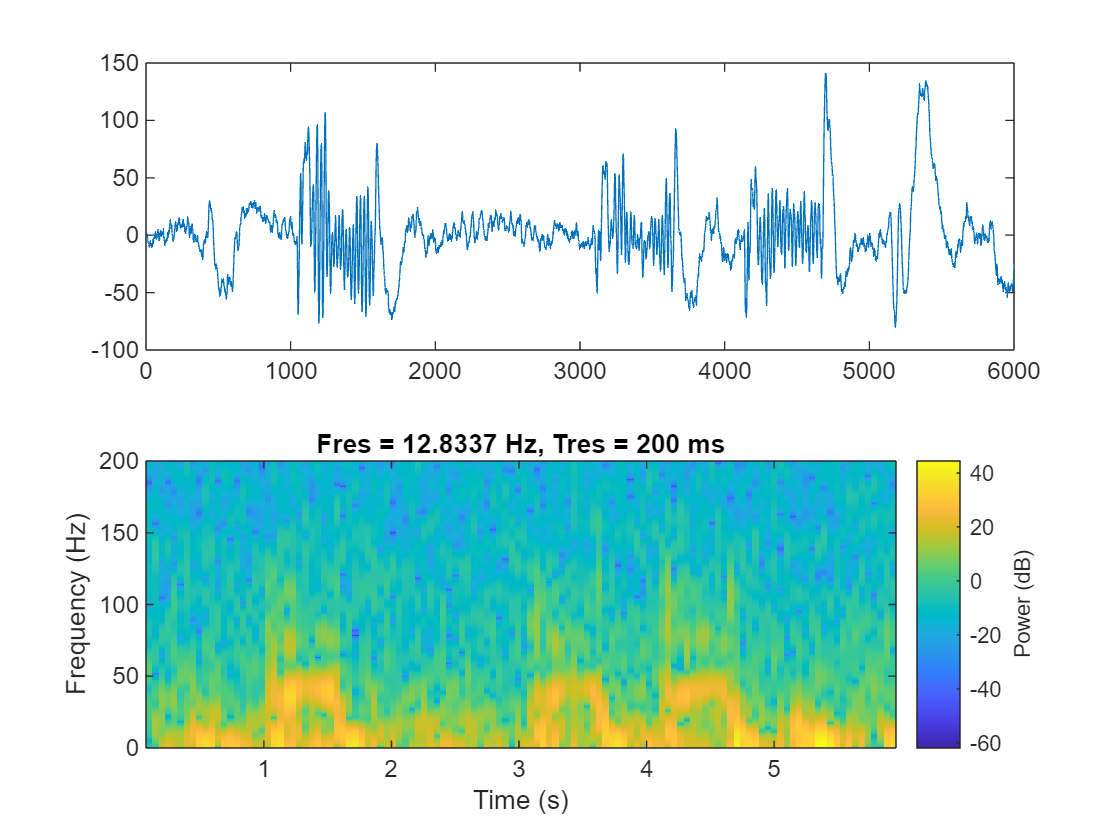


% Dimensions
[N, M, T] = size(X);

% Reshape data into 2D matrix for SVM
X_flat = reshape(X, [N, M * T]);

% Initialize weight matrix

Y = zeros(N, M);

% Perform MVPA for each group
for i = 1:N
    % Create binary labels for the current group
    labels = double(G == i);
    labels(labels == 0) = -1; % SVM requires binary labels -1 and 1
    
    % Train linear SVM
    SVMModel = fitcsvm(X_flat, labels, 'KernelFunction', 'linear', ...
                       'Standardize', true, 'ClassNames', [-1, 1]);
    
    % Extract weights for the linear classifier
    beta = SVMModel.Beta; % Coefficients for M*T features
    
    % Reshape weights back to M channels
    Y(i, :) = sum(reshape(beta, [M, T]), 2); % Sum over time dimension
end

end

t = linspace(-1, 5, 6000);
y = squeeze(mean(xG1(:, 1, :), 1));
% y = conv(y, [-1 2 -1], "same");
subplot(2, 1, 1);
plot(y);
subplot(2, 1, 2);
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 200], "TimeResolution", 0.2);

t = linspace(-1, 5, 6000);
y = squeeze(mean(xG2(:, 1, :), 1));
% y = conv(y, [-1 2 -1], "same");
subplot(2, 1, 1);
plot(y);
subplot(2, 1, 2);
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 200], "TimeResolution", 0.2);

## End